MSTR (Maximum Sustained Turn rate) for PROP ACFT

W=45000;      % Weight of aircraft [N]
S=28;         % Wing area [m^2]
Cd0=0.021;    % Lift independent drag
k=0.045;
Clmax=1.5;    % Max Lift Coefficient
Psh=900000;   % shaft power [W]
np=0.82;      % Propeller efficiency
nlim=3;       % Limit load factor
d=1.225;      % Density [kg/m^3], considered at mean sea level (MSL)
g=9.81;       % Gravitational acceleration [m/s^2]

Pa=np*Psh;    % Power Available

V=20:0.1:120;

n=(S/W)*sqrt(((Pa*d.*V)./(2*k*S))-((d*d*Cd0.*V.^4)./(4*k)));       % Load factor
Vstall=sqrt((2*W.*n)./(d*Clmax*S));


%[maxval_n,idx] = fun(fun==0)     % Max load factor
%V_maxval_n = V(idx)         % Value corresponding to Max load factor

%X_int=fsolve(fun,0);


MSTR (Maximum Sustained Turn Rate)

fprintf(' MSTR - Maximum Sustained Turn Rate ')

 MSTR - Maximum Sustained Turn Rate 

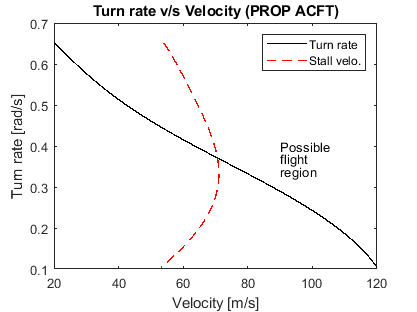


Cl=(2*n.*W)./(d.*V.*V.*S);       % Coefficient of lift
w=g*sqrt(n.*n-1)./V;             % Rate of Turn

plot(V,w,'k',"LineWidth",1)
hold on 
plot(Vstall,w,'r--',"LineWidth",1) 
hold off
title('Turn rate v/s Velocity (PROP ACFT)')
xlabel('Velocity [m/s]') 
ylabel('Turn rate [rad/s]') 
legend('Turn rate','Stall velo.')
text(90,0.4,'Possible')
text(90,0.37,'flight')
text(90,0.34,'region')


fprintf(' # Intersection of w v/s V and w v/s Vstall : ')

 # Intersection of w v/s V and w v/s Vstall : 


b_line1 = polyfit(V,w,4);
y_line1 = polyval(b_line1,Vstall);
x_int1 = interp1((y_line1 - w),Vstall,0)

x_int1 = 70.6176

y_int1 = polyval(b_line1,x_int1)

y_int1 = 0.3703


fprintf(' # Performance characteristics (MSTR) : ')

 # Performance characteristics (MSTR) : 


n = (S/W)*sqrt(((Pa*d*x_int1)/(2*k*S))-((d*d*Cd0*x_int1^4)/(4*k)));

if n<nlim
    n_MSTR = n;
    V_MSTR = x_int1;
    fprintf('n_MSTR = %f (Load Factor corresponding to MSTR)\n', n_MSTR)
    fprintf('V_MSTR = %f m/s(Velocity corresponding to MSTR)\n', V_MSTR)
else
    n_MSTR = nlim;
    fprintf('n_MSTR = %f (Load Factor corresponding to MSTR)\n', n_MSTR)
    A1 = (d*d*Cd0)/(4*k);
    B1 = -(Pa*d)/(2*S*k);
    C1 = (n_MSTR*n_MSTR*W*W)/(S*S);
    L1 = roots([A1 0 0 B1 C1]);
    V_MSTR=real(L1(imag(L1) == 0))
    fprintf('V_MSTR = %f m/s (Velocity corresponding to MSTR)\n', V_MSTR)
end

n_MSTR = 2.850039 (Load Factor corresponding to MSTR)


V_MSTR = 70.617584 m/s(Velocity corresponding to MSTR)



w_MSTR=g*sqrt((n_MSTR^2)-1)/V_MSTR;
fprintf('w_MSTR = %f rad/s (Maximum Turn Rate)\n', w_MSTR)

w_MSTR = 0.370748 rad/s (Maximum Turn Rate)



R_MSTR=(V_MSTR^2)/(g*sqrt(n_MSTR^2-1));
fprintf('R_MSTR = %f m (Turn Radius corresponding to MSTR)\n', R_MSTR)

R_MSTR = 190.473153 m (Turn Radius corresponding to MSTR)



t_2pi_MSTR=2*pi/w_MSTR;
fprintf('t_2pi_MSTR = %f s (Time to complete one turn corresponding to MSTR)\n', t_2pi_MSTR)

t_2pi_MSTR = 16.947311 s (Time to complete one turn corresponding to MSTR)



Cl_MSTR=(2*n_MSTR*W)/(S*d*V_MSTR^2);
fprintf('Cl_MSTR = %f (Lift coefficient corresponding to MSTR)\n', Cl_MSTR)

Cl_MSTR = 1.499593 (Lift coefficient corresponding to MSTR)


STR (Sharpest Turn Radius)

fprintf(' STR - Sharpest Turn Radius ')

 STR - Sharpest Turn Radius 

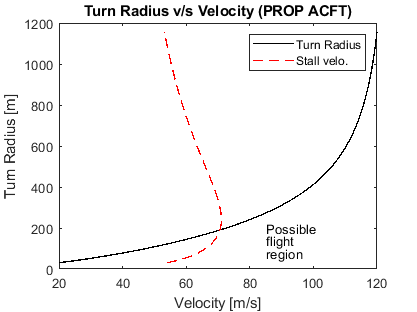


V=20:0.1:120;

n=(S/W)*sqrt(((Pa*d.*V)./(2*k*S))-((d*d*Cd0.*V.^4)./(4*k)));       % Load factor
Vstall=sqrt((2*W.*n)./(d*Clmax*S));

R=(V.*V)./(g*sqrt(n.*n-1));     % Turn Radius

plot(V,R,'k',"LineWidth",1)
hold on 
plot(Vstall,R,'r--',"LineWidth",1) 
hold off

title('Turn Radius v/s Velocity (PROP ACFT)')
xlabel('Velocity [m/s]') 
ylabel('Turn Radius [m]')
legend('Turn Radius','Stall velo.')
text(85,200,'Possible')
text(85,140,'flight')
text(85,80,'region')


fprintf(' # Intersection of R v/s V and R v/s Vstall : ')

 # Intersection of R v/s V and R v/s Vstall : 


b_line2 = polyfit(V,R,4);
y_line2 = polyval(b_line2,Vstall);
x_int2 = interp1((y_line2 - R),Vstall,0)

x_int2 = 70.7392

y_int2 = polyval(b_line2,x_int2)

y_int2 = 197.8166


fprintf(' # Performance characteristics (STR) : ')

 # Performance characteristics (STR) : 


n = (S/W)*sqrt(((Pa*d*x_int2)/(2*k*S))-((d*d*Cd0*x_int2^4)/(4*k)));

if n<nlim
    n_STR = n;
    V_STR = x_int2;
    fprintf('n_STR = %f (Load Factor corresponding to STR)\n', n_STR)
    fprintf('V_STR = %f m/s(Velocity corresponding to STR)\n', V_STR)
else
    n_STR = nlim;
    fprintf('n_STR = %f (Load Factor corresponding to STR)\n', n_STR)
    A1 = (d*d*Cd0)/(4*k);
    B1 = -(Pa*d)/(2*S*k);
    C1 = (n_STR*n_STR*W*W)/(S*S);
    L1 = roots([A1 0 0 B1 C1]);
    V_STR=real(L1(imag(L1) == 0))
    fprintf('V_STR = %f m/s (Velocity corresponding to STR)\n', V_STR)
end

n_STR = 2.850959 (Load Factor corresponding to STR)


V_STR = 70.739157 m/s(Velocity corresponding to STR)



w_STR=g*sqrt((n_STR^2)-1)/V_STR;
fprintf('w_STR = %f rad/s (Maximum Turn Rate)\n', w_STR)

w_STR = 0.370247 rad/s (Maximum Turn Rate)



R_STR=(V_STR^2)/(g*sqrt(n_STR^2-1));
fprintf('R_STR = %f m (Turn Radius corresponding to STR)\n', R_STR)

R_STR = 191.059171 m (Turn Radius corresponding to STR)



t_2pi_STR=2*pi/w_STR;
fprintf('t_2pi_STR = %f s (Time to complete one turn corresponding to STR)\n', t_2pi_STR)

t_2pi_STR = 16.970236 s (Time to complete one turn corresponding to STR)



Cl_STR=(2*n_STR*W)/(S*d*V_STR^2);
fprintf('Cl_STR = %f (Lift coefficient corresponding to STR)\n', Cl_STR)

Cl_STR = 1.494926 (Lift coefficient corresponding to STR)


MLT (Maximum Load Factor Turn)

 
fprintf(' MLT - Maximum Load factor Turn ')

 MLT - Maximum Load factor Turn 

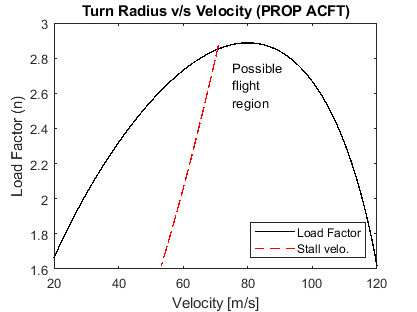


V=20:0.1:120;
n=(S/W)*sqrt(((Pa*d.*V)./(2*k*S))-((d*d*Cd0.*V.^4)./(4*k)));       % Load factor

plot(V,n,'k',"LineWidth",1) 
hold on 
plot(Vstall,n,'r--',"LineWidth",1) 
hold off 
title('Turn Radius v/s Velocity (PROP ACFT)')
xlabel('Velocity [m/s]') 
ylabel('Load Factor (n)')
legend({'Load Factor','Stall velo.'},'Location','southeast')
text(75,2.75,'Possible')
text(75,2.65,'flight')
text(75,2.55,'region')


fprintf(' # Intersection of n v/s V and n v/s Vstall : ')

 # Intersection of n v/s V and n v/s Vstall : 


b_line3 = polyfit(V,n,4);
y_line3 = polyval(b_line3,Vstall);
x_int3 = interp1((y_line3-n),Vstall,0)

x_int3 = 70.5599

y_int3 = polyval(b_line3,x_int3)

y_int3 = 2.8462

MLT (Direct method)

fprintf(' # Performance characteristics (MLT) : ')

 # Performance characteristics (MLT) : 


V_n_max=(Pa/(2*S*d*Cd0))^(1/3);
fprintf('V_n_max = %f m/s (Velocity corresponding to MLT)\n', V_n_max)

V_n_max = 80.014922 m/s (Velocity corresponding to MLT)



n_max=(S/W)*sqrt(((Pa*d)/(2*S*k))*V_n_max-((d*d*Cd0)/(4*k))*V_n_max^4);
fprintf('n_max = %f (Maximum Load Factor corresponding to MLT)\n', n_max)

n_max = 2.887072 (Maximum Load Factor corresponding to MLT)



R_n_max=(V_n_max^2)/(g*sqrt(n_max*n_max-1));
fprintf('R_n_max = %f m (Turn Radius corresponding to MLT)\n', R_n_max)

R_n_max = 240.972484 m (Turn Radius corresponding to MLT)



w_n_max=V_n_max/R_n_max;
fprintf('w_n_max = %f rad/s (Velocity corresponding to MLT)\n', w_n_max)

w_n_max = 0.332050 rad/s (Velocity corresponding to MLT)



t_2pi_n_max=2*pi/w_n_max;
fprintf('t_2pi_n_max = %f s (Time to complete one turn corresponding to MLT)\n', t_2pi_n_max)

t_2pi_n_max = 18.922405 s (Time to complete one turn corresponding to MLT)



Cl_n_max=(2*n_max*W)/(S*d*V_n_max^2);
fprintf('Cl_n_max = %f (Lift coefficient corresponding to Max n Turn)\n', Cl_n_max)

Cl_n_max = 1.183216 (Lift coefficient corresponding to Max n Turn)
